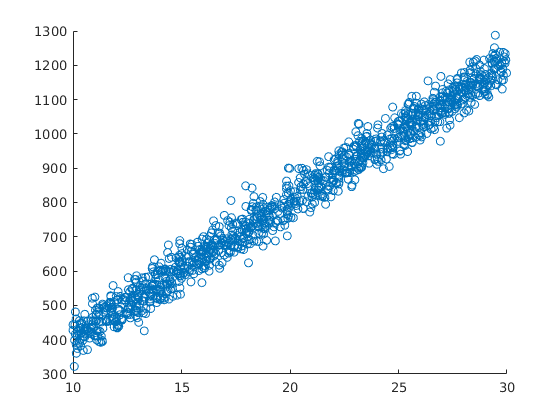

% regresion lineal una var
% Parámetros
A0 = 5;
A1 = 40;

N_dat = 1200;

%Modelo + ruido
x = 20*rand(N_dat,1) + 10;
y = A0 + A1*x;
y = y+35*randn(N_dat,1);
[xp,I] = sort(x);
yp = y(I);
scatter(xp,yp)


%csv
T = table(y,x);
writetable(T,'Lin_Data.csv')

El modelo multivariado

%regresion lineal multivar
%Parametros adicionales
A2 = 10;
A3 = -4.8;
A4 = 1.5;
A5 = 5.3;
A6 = -7.8;

%Modelo + ruido
x1 = x;
x2 = 10*rand(N_dat,1) - 5;
x3 = 7 * rand(N_dat,1) - 10;
x4 = 12.5 * rand(N_dat,1) + 20;
x5 = 1.5 * rand(N_dat,1) -8;
x6 = 3.8 * rand(N_dat,1) + 10;
y = A0 + A1*x1 + A2*x2 + A3*x3 + A4*x4 + A5*x5 + A6*x6;
y = y+35*randn(N_dat,1);

%csv
T=table(y,x1,x2,x3,x4,x5,x6);
writetable(T,'MLin_Data.csv')